# 250 Group Project - Spring 2023 - Yuan & Xiang

## Data: Online Shoppers Purchasing Intention

## 0. Data Preparation

% (1) clear & load dataset
clear
clc
close all

data=readtable('online_shoppers_intention.csv');

summary(data);

Variables:

    Administrative: 12330×1 double

        Values:

            Min           0   
            Median        1   
            Max          27   

    Administrative_Duration: 12330×1 double

        Values:

            Min             0 
            Median        7.5 
            Max        3398.8 

    Informational: 12330×1 double

        Values:

            Min           0   
            Median        0   
            Max          24   

    Informational_Duration: 12330×1 double

        Values:

            Min             0 
            Median          0 
            Max        2549.4 

    ProductRelated: 12330×1 double

        Values:

            Min           0   
            Median       18   
            Max         705   

    ProductRelated_Duration: 12330×1 double

        Values:

            Min             0 
            Median     598.94 
           

data(1:5,:)

ans = 5×18 table
    Administrative    Administrative_Duration    Informational    Informational_Duration    ProductRelated    ProductRelated_Duration    BounceRates    ExitRates    PageValues    SpecialDay     Month     OperatingSystems    Browser    Region    TrafficType         VisitorType          Weekend      Revenue 
    ______________    _______________________    _____________    ______________________    ______________    _______________________    ___________    _________    __________    __________    

%check missing values
missingCounts = sum(ismissing(data));
variableNames = data.Properties.VariableNames;
for i = 1:numel(variableNames)
    fprintf('Column: %s\n', variableNames{i});
    fprintf('Missing Values: %d\n', missingCounts(i));
    fprintf('\n');
end

Column: Administrative


Missing Values: 0


Column: Administrative_Duration


Missing Values: 0


Column: Informational


Missing Values: 0


Column: Informational_Duration


Missing Values: 0


Column: ProductRelated


Missing Values: 0


Column: ProductRelated_Duration


Missing Values: 0


Column: BounceRates


Missing Values: 0


Column: ExitRates


Missing Values: 0


Column: PageValues


Missing Values: 0


Column: SpecialDay


Missing Values: 0


Column: Month


Missing Values: 0


Column: OperatingSystems


Missing Values: 0


Column: Browser


Missing Values: 0


Column: Region


Missing Values: 0


Column: TrafficType


Missing Values: 0


Column: VisitorType


Missing Values: 0


Column: Weekend


Missing Values: 0


Column: Revenue


Missing Values: 0


%check data type
[numRows, numCols] = size(data);
fprintf('Shape of T: %d rows, %d columns\n', numRows, numCols);

Shape of T: 12330 rows, 18 columns


%disp(T) 
variableNames = data.Properties.VariableNames;
variableTypes = cell(1, numel(variableNames));
for i = 1:numel(variableNames)
    variableTypes{i} = class(data.(variableNames{i}));
end
disp(variableTypes);

  Columns 1 through 11

    {'double'}    {'double'}    {'double'}    {'double'}    {'double'}    {'double'}    {'double'}    {'double'}    {'double'}    {'double'}    {'cell'}

  Columns 12 through 18

    {'double'}    {'double'}    {'double'}    {'double'}    {'cell'}    {'cell'}    {'cell'}



% (2) Data Manipulation
% A. Transform categorical variables
data.Weekend = categorical(data.Weekend);
data.Month = categorical(data.Month);
Month.name = categorical(categories(data.Month));
Month.count = countcats(data.Month);
data.VisitorType = categorical(data.VisitorType);
data.Revenue = categorical(data.Revenue);

% B. Make a copy and using log10 to transform numerical data
tdata = data;
tdata{:,1:10} = log(tdata{:,1:10}+1);

% C. Transform categorical data to numbers for MDS
[~, ~, tdata.Month] = unique(tdata.Month);
[~, ~, tdata.Weekend] = unique(tdata.Weekend);
[~, ~, tdata.VisitorType] = unique(tdata.VisitorType);

## 1. Visualization

## (1)Categorical Variables

**Bar plot of 4 categorical variables**

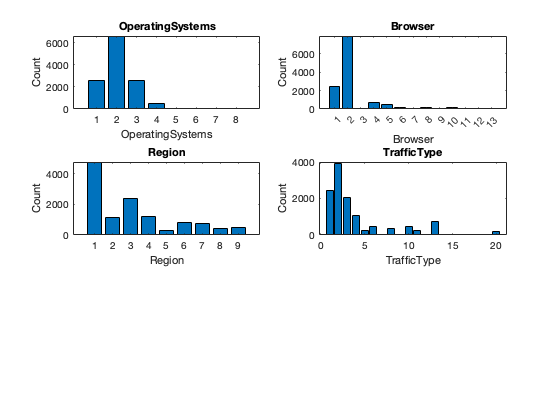

% Define the variables
variables = {'OperatingSystems', 'Browser', 'Region', 'TrafficType'};

% Create a bar plot for each variable
figure;
for i = 1:numel(variables)
    subplot(3, 2, i);
    variableData = data.(variables{i});
    valueCounts = countcats(categorical(variableData));
    bar(valueCounts);
    xlabel(variables{i});
    ylabel('Count');
    title(variables{i});
end

**Pie plot of 4 categorical variables**

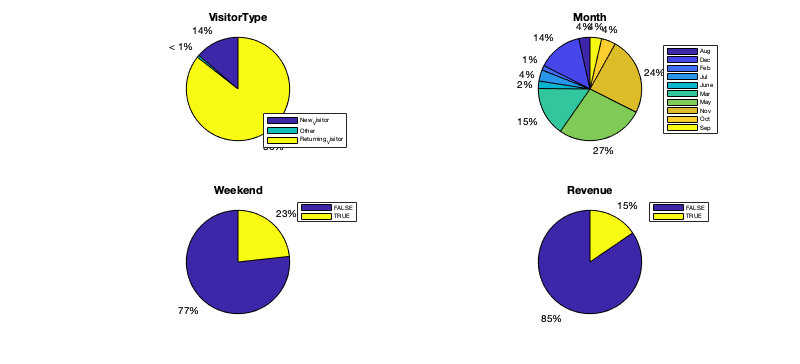

% Define the variables
variables = {'VisitorType', 'Month','Weekend', 'Revenue'};

% Create a 1x3 pie plot
figure('Position', [100, 100, 1500, 500]); 
for i = 1:numel(variables)
    subplot(2, 2, i);
    variableData = data.(variables{i});
    
    % Convert data to categorical and get unique categories
    catVariableData = categorical(variableData);
    categoryNames = unique(catVariableData);
    
    % Count occurrences of each unique value
    valueCounts = countcats(catVariableData);
    
    % Draw pie chart and add legend
    pie(valueCounts);
    lgd = legend(categoryNames, 'Location', 'best');
    lgd.FontSize = 6;  % Modify this value as needed
    title(variables{i});
end

**Bar plot of each variable vs Revenue**

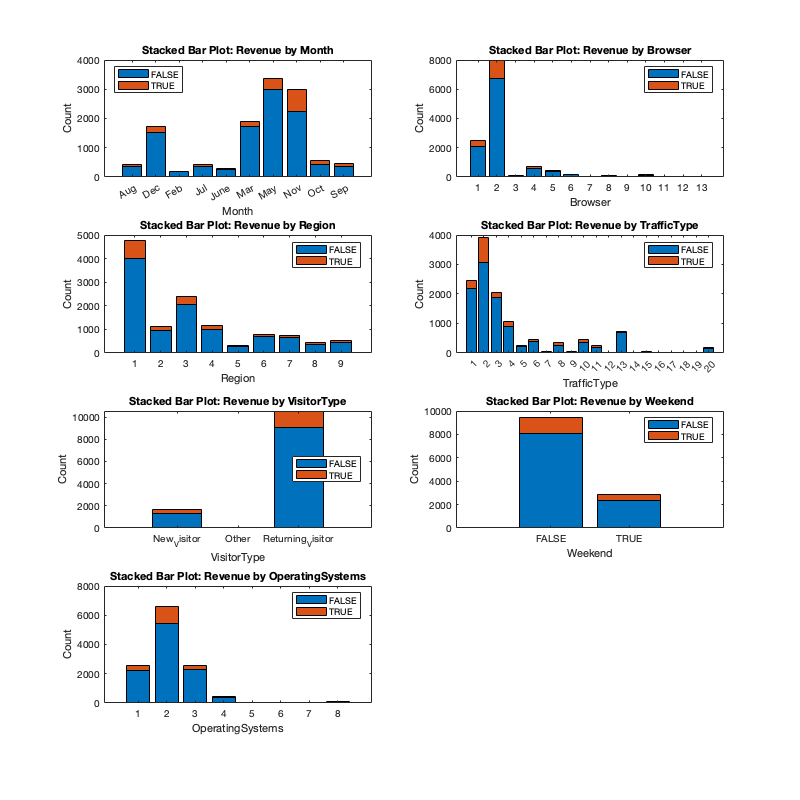

% Convert categorical variables to categorical if not already
data.OperatingSystems = categorical(data.OperatingSystems);
data.Browser = categorical(data.Browser);
data.Region = categorical(data.Region);
data.TrafficType = categorical(data.TrafficType);
data.VisitorType = categorical(data.VisitorType);
data.Weekend = categorical(data.Weekend);
data.Revenue = categorical(data.Revenue);
data.Month = categorical(data.Month);

% Create a contingency table and plot for each variable
variables = {'Month', 'Browser', 'Region', 'TrafficType', 'VisitorType', 'Weekend','OperatingSystems',};
figure('Position', [100, 100, 1000, 1000]); % Adjust figure size as needed

for i = 1:numel(variables)
    subplot(4, 2, i);
    [C, categoryNames, ~] = crosstab(data.(variables{i}), data.Revenue);
    bar(C, 'stacked');
    xlabel(variables{i});
    ylabel('Count');
    title(['Stacked Bar Plot: Revenue by ' variables{i}]);
    
    % Set the x-labels with the unique values for each variable
    uniqueValues = unique(data.(variables{i}));
    set(gca, 'XTick', 1:numel(uniqueValues));
    set(gca, 'XTickLabel', uniqueValues);
    
    legend(unique(data.Revenue), 'Location', 'best');
end

## (2) Numerical Variables

## A. 1 Single Numerical Variable

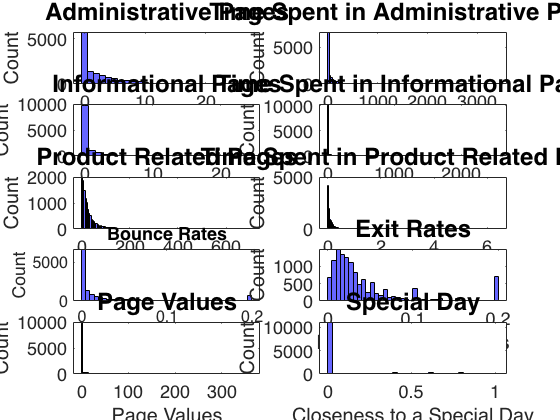

% Raw Data
figure;

% Plot 1: Administrative
subplot(5, 2, 1)
histogram(data.Administrative, 'Normalization', 'count', ...
                 'FaceColor', 'blue');
set(gca, 'fontsize', 18)
xlabel('Pages')
ylabel('Count')
title('Administrative Pages', 'fontsize', 24)

% Plot 2: Administrative_Duration
subplot(5, 2, 2)
a=histogram(data.Administrative_Duration, 'Normalization', 'count', ...
                 'FaceColor', 'blue');
set(gca, 'fontsize', 18)
xlabel('Time')
ylabel('Count')
title('Time Spent in Administrative Pages','fontsize', 24)

% Plot 3: Informational
subplot(5, 2, 3)
a=histogram(data.Informational, 'Normalization', 'count', ...
                 'FaceColor', 'blue');
xlabel('Pages')
ylabel('Count')
set(gca, 'fontsize', 18)
title('Informational Pages','fontsize', 24)

% Plot 4: Informational_Duration
subplot(5, 2, 4)
a=histogram(data.Informational_Duration, 'Normalization', 'count', ...
                 'FaceColor', 'blue');
xlabel('Time')
ylabel('Count')
set(gca, 'fontsize', 18)
title('Time Spent in Informational Pages','fontsize', 24)

% Plot 5: ProductRelated
subplot(5, 2, 5)
a=histogram(data.ProductRelated, 'Normalization', 'count', ...
                 'FaceColor', 'blue');
xlabel('Pages')
ylabel('Count')
set(gca, 'fontsize', 18)
title('Product Related Pages','fontsize', 24)

% Plot 6: ProductRelated_Duration
subplot(5, 2, 6)
a=histogram(data.ProductRelated_Duration, 'Normalization', 'count', ...
                 'FaceColor', 'blue');
xlabel('Time')
ylabel('Count')
set(gca, 'fontsize', 18)
title('Time Spent in Product Related Pages','fontsize', 24)

% Plot 7: BounceRates
subplot(5, 2, 7)
a=histogram(data.BounceRates, 'Normalization', 'count', ...
                 'FaceColor', 'blue');
xlabel('Percentage of Visitors')
ylabel('Count')
set(gca, 'fontsize', 16)
title('Bounce Rates','fontsize', 18)

% Plot 8: ExitRates
subplot(5, 2, 8)

a=histogram(data.ExitRates, 'Normalization', 'count', ...
                 'FaceColor', 'blue');
xlabel('Percentage of Visitors')
ylabel('Count')
set(gca, 'fontsize', 18)
title('Exit Rates','fontsize', 24)

% Plot 9: PageValues
subplot(5, 2, 9)
a=histogram(data.PageValues, 'Normalization', 'count', ...
                 'FaceColor', 'blue');
xlabel('Page Values')
ylabel('Count')
set(gca, 'fontsize', 18)
title('Page Values','fontsize', 24)

% Plot 10: SpecialDay
subplot(5, 2, 10)
a=histogram(data.SpecialDay, 'Normalization', 'count', ...
                 'FaceColor', 'blue');
xlabel('Closeness to a Special Day')
ylabel('Count')
set(gca, 'fontsize', 18)
title('Special Day','fontsize', 24)

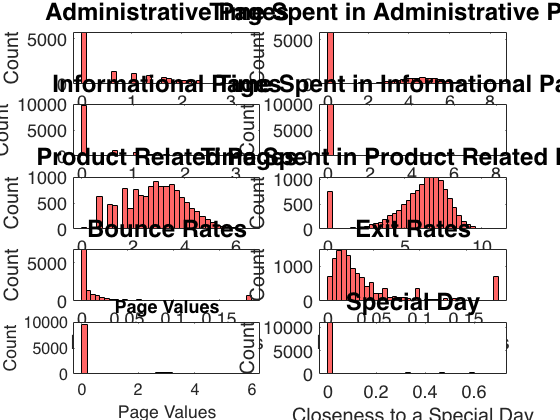

% Log Data
figure;

% Plot 1: Administrative
subplot(5, 2, 1)
histogram(tdata.Administrative, 'Normalization', 'count', ...
                 'FaceColor', 'red');
set(gca, 'fontsize', 18)
xlabel('Pages')
ylabel('Count')
title('Administrative Pages', 'fontsize', 24)

% Plot 2: Administrative_Duration
subplot(5, 2, 2)
a=histogram(tdata.Administrative_Duration, 'Normalization', 'count', ...
                 'FaceColor', 'red');
set(gca, 'fontsize', 18)
xlabel('Time')
ylabel('Count')
title('Time Spent in Administrative Pages','fontsize', 24)

% Plot 3: Informational
subplot(5, 2, 3)
a=histogram(tdata.Informational, 'Normalization', 'count', ...
                 'FaceColor', 'red');
xlabel('Pages')
ylabel('Count')
set(gca, 'fontsize', 18)
title('Informational Pages','fontsize', 24)

% Plot 4: Informational_Duration
subplot(5, 2, 4)
a=histogram(tdata.Informational_Duration, 'Normalization', 'count', ...
                 'FaceColor', 'red');
xlabel('Time')
ylabel('Count')
set(gca, 'fontsize', 18)
title('Time Spent in Informational Pages','fontsize', 24)

% Plot 5: ProductRelated
subplot(5, 2, 5)
a=histogram(tdata.ProductRelated, 'Normalization', 'count', ...
                 'FaceColor', 'red');
xlabel('Pages')
ylabel('Count')
set(gca, 'fontsize', 18)
title('Product Related Pages','fontsize', 24)

% Plot 6: ProductRelated_Duration
subplot(5, 2, 6)
a=histogram(tdata.ProductRelated_Duration, 'Normalization', 'count', ...
                 'FaceColor', 'red');
xlabel('Time')
ylabel('Count')
set(gca, 'fontsize', 18)
title('Time Spent in Product Related Pages','fontsize', 24)

% Plot 7: BounceRates
subplot(5, 2, 7)
a=histogram(tdata.BounceRates, 'Normalization', 'count', ...
                 'FaceColor', 'red');
xlabel('Percentage of Visitors')
ylabel('Count')
set(gca, 'fontsize', 18)
title('Bounce Rates','fontsize', 24)

% Plot 8: ExitRates
subplot(5, 2, 8)
a=histogram(tdata.ExitRates, 'Normalization', 'count', ...
                 'FaceColor', 'red');
xlabel('Percentage of Visitors')
ylabel('Count')
set(gca, 'fontsize', 18)
title('Exit Rates','fontsize', 24)

% Plot 9: PageValues
subplot(5, 2, 9)
a=histogram(tdata.PageValues, 'Normalization', 'count', ...
                 'FaceColor', 'red');
xlabel('Page Values')
ylabel('Count')
set(gca, 'fontsize', 16)
title('Page Values','fontsize', 18)

% Plot 10: SpecialDay
subplot(5, 2, 10)
a=histogram(tdata.SpecialDay, 'Normalization', 'count', ...
                 'FaceColor', 'red');
xlabel('Closeness to a Special Day')
ylabel('Count')
set(gca, 'fontsize', 18)
title('Special Day','fontsize', 24)

## B. Pairs of Variables 1: 2 Numerical Variables

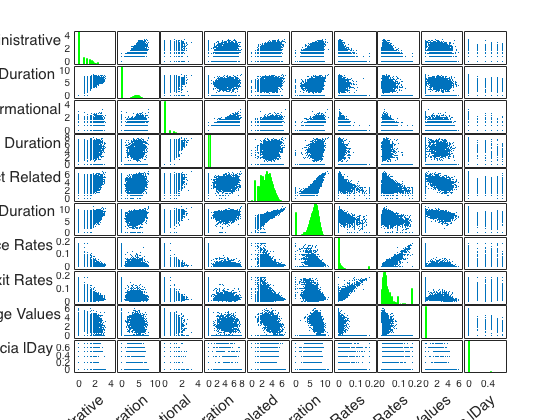

% Pairwise Scatter
figure;
[~,A10plot,~,H10plot,~] = plotmatrix(table2array(tdata(:,1:10)));
varNames=["Administrative","Administrative Duration",...
          "Informational","Informational Duration","Product Related",...
          "Product Related Duration","Bounce Rates","Exit Rates","Page Values","Specia lDay"];
for i = 1:10
    H10plot(i).FaceColor  = 'g';
    H10plot(i).EdgeColor  = 'g';
    xlabel(A10plot(end, i), varNames(i), "Rotation", 40,"HorizontalAlignment", "right", 'fontsize',15)
    ylabel(A10plot(i,1), varNames(i), "Rotation", 0, "HorizontalAlignment", "right", 'fontsize', 15)
end 

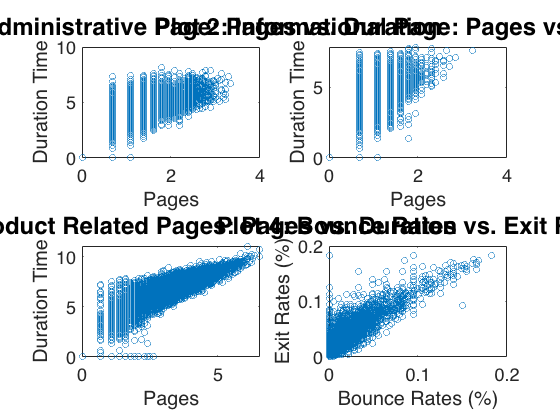

% To present
figure; 
% Plot 1: Administrative vs. Administrative Duration
subplot(2,2,1)
scatter(tdata.Administrative, tdata.Administrative_Duration)
xlabel('Pages')
ylabel('Duration Time')
set(gca, 'fontsize', 18)
title('Plot 1: Administrative Page: Pages vs. Duration','fontsize', 24)
box on

% Plot 2: Informational vs. Informational Duration
subplot(2,2,2)
scatter(tdata.Informational, tdata.Informational_Duration)
xlabel('Pages')
ylabel('Duration Time')
set(gca, 'fontsize', 18)
title('Plot 2: Informational Page: Pages vs. Duration','fontsize', 24)
box on

% Plot 3: Product Related vs. Product Related Duration
subplot(2,2,3)
scatter(tdata.ProductRelated, tdata.ProductRelated_Duration)
xlabel('Pages')
ylabel('Duration Time')
set(gca, 'fontsize', 18)
title('Plot 3: Product Related Pages: Pages vs. Duration','fontsize', 24)
box on

% Plot 4 Bounce Rates vs. Exit Rates
subplot(2,2,4)
scatter(tdata.BounceRates, tdata.ExitRates) 
set(gca, 'fontsize', 18)
xlabel('Bounce Rates (%)')
ylabel('Exit Rates (%)')
title('Plot 4: Bounce Rates vs. Exit Rates', 'fontsize', 24)
box on

## C. Pairs of Variables 2: 1 Numerical Variable & 1 Categorical Variable

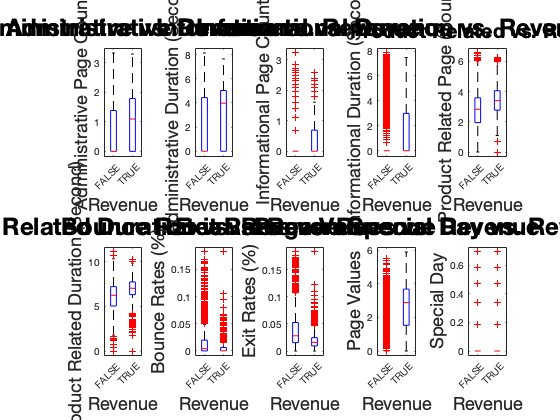

% All numerical
figure; 
% Plot 1:  Administrative vs. Revenue
subplot(2,5,1)
boxplot(tdata.Administrative, tdata.Revenue);
xlabel('Revenue','fontsize', 18)
ylabel('Administrative Page Count','fontsize', 18)
title('Administrative vs. Revenue','fontsize', 24)

% Plot 2:  Administrative Duration vs. Revenue
subplot(2,5,2)
boxplot(tdata.Administrative_Duration, tdata.Revenue) 
xlabel('Revenue','fontsize', 18)
ylabel('Administrative Duration (Second)','fontsize', 18)
title('Administrative Duration vs. Revenue','fontsize', 24)

% Plot 3: Informational vs. Revenue
subplot(2,5,3)
boxplot(tdata.Informational, tdata.Revenue);
xlabel('Revenue','fontsize', 18)
ylabel('Informational Page Count','fontsize', 18)
title('Informational vs. Revenue','fontsize', 24)

% Plot 4: Informational Duration vs. Revenue
subplot(2,5,4)
boxplot(tdata.Informational_Duration, tdata.Revenue);
xlabel('Revenue','fontsize', 18)
ylabel('Informational Duration (Second)','fontsize', 18)
title('Informational Duration vs. Revenue','fontsize', 24)

% Plot 5: Product Related vs. Revenue
subplot(2,5,5)
boxplot(tdata.ProductRelated, tdata.Revenue);
xlabel('Revenue','fontsize', 18)
ylabel('Product Related Page (Count)','fontsize', 18)
title('Product Related vs. Revenue','fontsize', 20)

% Plot 6: Product Related Duration vs. Revenue
subplot(2,5,6)
boxplot(tdata.ProductRelated_Duration, tdata.Revenue);
xlabel('Revenue','fontsize', 18)
ylabel('Product Related Duration (Second)','fontsize', 18)
title('Product Related Duration vs. Revenue','fontsize', 24)

% Plot 7: Bounce Rates vs. Revenue
subplot(2,5,7)
boxplot(tdata.BounceRates, tdata.Revenue);
xlabel('Revenue','fontsize', 18)
ylabel('Bounce Rates (%)','fontsize', 18)
title('Bounce Rates vs. Revenue','fontsize', 24)

% Plot 8: Exit Rates vs. Revenue
subplot(2,5,8)
boxplot(tdata.ExitRates, tdata.Revenue);
%set(gca, 'fontsize')
xlabel('Revenue','fontsize', 18)
ylabel('Exit Rates (%)','fontsize', 18)
title('Exit Rates vs. Revenue','fontsize', 24)

% Plot 9: Page Values vs. Revenue
subplot(2,5,9)
boxplot(tdata.PageValues, tdata.Revenue);
xlabel('Revenue','fontsize', 18)
ylabel('Page Values','fontsize', 18)
title('Page Values vs. Revenue','fontsize', 24)

% Plot 10: Special Day vs. Revenue
subplot(2,5,10)
boxplot(tdata.SpecialDay, tdata.Revenue);
xlabel('Revenue','fontsize', 18)
ylabel('Special Day','fontsize', 18)
title('Special Day vs. Revenue','fontsize', 24)

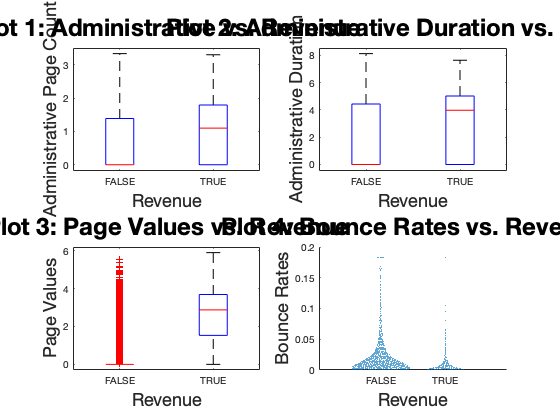

% To present
figure; 
% Plot 1:  Administrative vs. Revenue
subplot(2,2,1)
boxplot(tdata.Administrative, tdata.Revenue);
xlabel('Revenue','fontsize', 18)
ylabel('Administrative Page Count','fontsize', 18)
title('Plot 1: Administrative vs. Revenue','fontsize', 24)

% Plot 2:  Administrative Duration vs. Revenue
subplot(2,2,2)
boxplot(tdata.Administrative_Duration, tdata.Revenue) 
xlabel('Revenue','fontsize', 18)
ylabel('Administrative Duration','fontsize', 18)
title('Plot 2: Administrative Duration vs. Revenue','fontsize', 24)

% Plot 3: Page Values vs. Revenue
subplot(2,2,3)
boxplot(tdata.PageValues, tdata.Revenue);
xlabel('Revenue','fontsize', 18)
ylabel('Page Values','fontsize', 18)
title('Plot 3: Page Values vs. Revenue','fontsize', 24)

% Plot 4: Bounce Rates vs. Revenue
subplot(2,2,4)
swarmchart(tdata.Revenue, tdata.BounceRates, 1,"filled");
xlabel('Revenue','fontsize', 18)
ylabel('Bounce Rates','fontsize', 18)
title('Plot 4: Bounce Rates vs. Revenue','fontsize', 24)

median(tdata.Administrative(tdata.Revenue=='TRUE'))

ans = 1.0986

median(tdata.Administrative(tdata.Revenue=='FALSE'))

ans = 0

mean(tdata.Administrative(tdata.Revenue=='TRUE'))

ans = 1.1258

mean(tdata.Administrative(tdata.Revenue=='FALSE'))

ans = 0.7368

median(tdata.Administrative_Duration(tdata.Revenue=='TRUE'))

ans = 3.9772

median(tdata.Administrative_Duration(tdata.Revenue=='FALSE'))

ans = 0

mean(tdata.Administrative_Duration(tdata.Revenue=='TRUE'))

ans = 3.2271

mean(tdata.Administrative_Duration(tdata.Revenue=='FALSE'))

ans = 2.1381

median(tdata.PageValues(tdata.Revenue=='TRUE'))

ans = 2.8768

median(tdata.PageValues(tdata.Revenue=='FALSE'))

ans = 0

mean(tdata.PageValues(tdata.Revenue=='TRUE'))

ans = 2.5058

mean(tdata.PageValues(tdata.Revenue=='FALSE'))

ans = 0.2796

## D. Triples of Variables

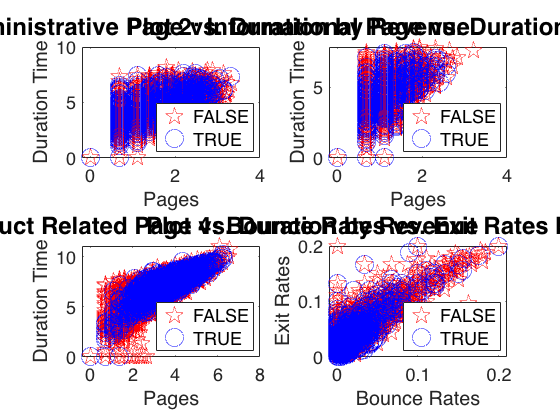

% 2 Numerical & 1 Categorical
figure;
% Plot 1: Administrative, Administrative Duration & Revenue
levels = categories(tdata.Revenue);
figure;
subplot(2,2,1)
gscatter(tdata.Administrative, tdata.Administrative_Duration, tdata.Revenue, 'rbm', 'po.', 18)
set(gca, 'fontsize', 18)
xlabel('Pages')
ylabel('Duration Time')
title('Plot 1: Administrative Page vs. Duration by Revenue', 'fontsize', 24)
legend(levels, 'fontsize', 18, 'Location', 'Southeast')
box on

% Plot 2: Informational, Informational Duration & Revenue
levels = categories(tdata.Revenue);
subplot(2,2,2)
gscatter(tdata.Informational, tdata.Informational_Duration, tdata.Revenue, 'rbm', 'po.', 18)
set(gca, 'fontsize', 18)
xlabel('Pages')
ylabel('Duration Time')
title('Plot 2: Informational Page vs. Duration by Revenue', 'fontsize', 24)
legend(levels, 'fontsize', 18, 'Location', 'Southeast')
box on

% Plot 3: Product Related, Product Related Duration & Revenue
levels = categories(tdata.Revenue);
subplot(2,2,3)
gscatter(tdata.ProductRelated, tdata.ProductRelated_Duration, tdata.Revenue, 'rbm', 'po.', 18)
set(gca, 'fontsize', 18)
xlabel('Pages')
ylabel('Duration Time')
title('Plot 3: Product Related Page vs. Duration by Revenue', 'fontsize', 24)
legend(levels, 'fontsize', 18, 'Location', 'Southeast')
box on

% Plot 4: Bounce Rates, Exit Rates & Revenue
levels = categories(categorical(data.Revenue));
subplot(2,2,4)
gscatter(data.BounceRates, data.ExitRates, data.Weekend, 'rbm', 'po.', 18)
set(gca, 'fontsize', 18)
xlabel('Bounce Rates')
ylabel('Exit Rates')
title('Plot 4: Bounce Rates vs. Exit Rates by Revenue', 'fontsize', 24)
legend(levels, 'fontsize', 18, 'Location', 'Southeast')
box on

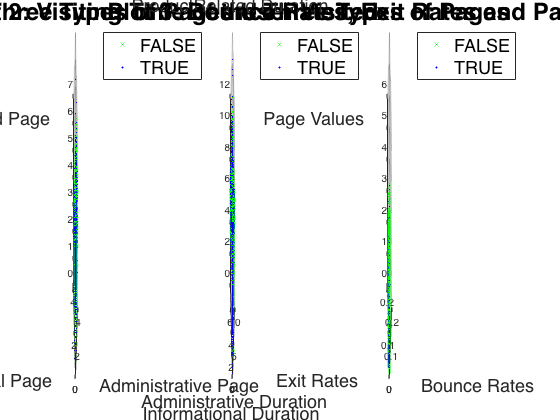

% 3 Numerical Variables

levels = categories(tdata.Revenue);

figure;
% plot 1:  Administrative, Informational & Product Related
subplot(1,3,1)
scatter3(tdata.Administrative(data.Revenue=='TRUE'), tdata.Informational(data.Revenue=='TRUE'), tdata.ProductRelated(data.Revenue=='TRUE'), 6, 'g', 'x');
hold on;
scatter3(tdata.Administrative(data.Revenue=='FALSE'), tdata.Informational(data.Revenue=='FALSE'), tdata.ProductRelated(data.Revenue=='FALSE'), 6, 'b', '.');
hold off;
xlabel('Administrative Page', 'fontsize',18)
ylabel('Informational Page', 'fontsize',18)
zlabel('Product Related Page', 'fontsize',18)
title('Plot 1: Quantity of Three Types of Pages User Visited', 'fontsize',24)
legend(levels, 'fontsize', 18)

% Plot 2: Administrative Duration, Informational Duration & Product Related Duration
subplot(1,3,2)
scatter3(tdata.Administrative_Duration(data.Revenue=='TRUE'), tdata.Informational_Duration(data.Revenue=='TRUE'), tdata.ProductRelated_Duration(data.Revenue=='TRUE'), 6, 'g', 'x');
hold on;
scatter3(tdata.Administrative_Duration(data.Revenue=='FALSE'), tdata.Informational_Duration(data.Revenue=='FALSE'), tdata.ProductRelated_Duration(data.Revenue=='FALSE'), 6, 'b', '.');
hold off;
xlabel('Administrative Duration', 'fontsize',18)
ylabel('Informational Duration', 'fontsize',18)
zlabel('ProductRelated Duration', 'fontsize',18)
title('Plot 2: Visiting Time of the Three Types of Pages', 'fontsize',24)
legend(levels, 'fontsize', 18)

% Plot 3: Bounce Rates, Exit Rates & Page Values
subplot(1,3,3)
scatter3(tdata.BounceRates(data.Revenue=='TRUE'), tdata.ExitRates(data.Revenue=='TRUE'), tdata.PageValues(data.Revenue=='TRUE'), 6, 'g', 'x');
hold on;
scatter3(tdata.BounceRates(data.Revenue=='FALSE'), tdata.ExitRates(data.Revenue=='FALSE'), tdata.PageValues(data.Revenue=='FALSE'), 6, 'b', '.');
hold off;
xlabel('Bounce Rates', 'fontsize',18)
ylabel('Exit Rates', 'fontsize',18)
zlabel('Page Values', 'fontsize',18)
title('Plot 3: Bounce Rates, Exit Rates and Page Values', 'fontsize',24)
legend(levels, 'fontsize', 18)

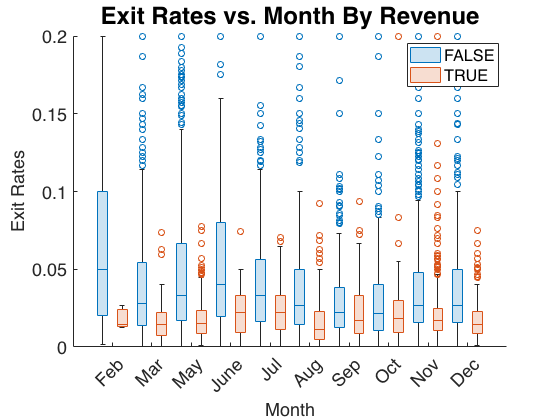

% 1 numerical with 2 categorical.

figure;

monthOrder = {'Feb','Mar','May','June','Jul','Aug','Sep', 'Oct', 'Nov', 'Dec'};
data.Month = categorical(data.Month,monthOrder);
boxchart(data.Month,data.ExitRates,'GroupByColor',data.Revenue)
ylabel('Exit Rates')
a = get(gca, 'XTickLabel');
set(gca, 'XTickLabel', a, 'fontsize', 18);
xlabel('Month','fontsize', 18)
ylabel('Exit Rates','fontsize', 18)
title('Exit Rates vs. Month By Revenue','fontsize', 24)
legend

## 2. Dimension Reduction Methods

## **(1)PCA:Linear Unsupervied**

**Correlation Matrix**

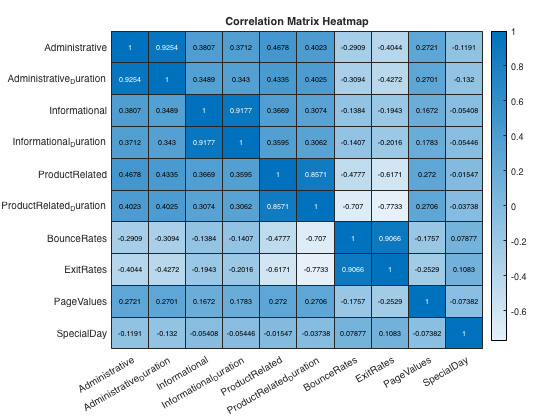

% Extract the numerical data from table T
X = table2array(tdata(:, 1:10));

% Normalize the numerical data
Xnorm = normalize(X);

% Get the variable names
variableNames = tdata.Properties.VariableNames(1:10);

% Calculate the correlation matrix
correlation_matrix = corrcoef(Xnorm);

% Create a heatmap with variable names
figure;
heatmap(variableNames, variableNames, correlation_matrix);
title('Correlation Matrix Heatmap');

% Extract the revenue labels
Y = categorical(tdata.Revenue);
% Perform PCA 
[coefficients, scores,latent, tsquared, explained] = pca(Xnorm);
% Extract the revenue labels
revenues = unique(tdata.Revenue)

revenues = 2×1 categorical array
     FALSE 
     TRUE 


**Scree Plot**

% Plot the explained variance ratio
explained

explained =    43.9194
   17.2066
   11.7530
    9.6475
    8.5978
    5.6110
    1.0595
    0.8446
    0.7665
    0.5941


idx = find(cumsum(explained)>95,1)

idx = 6

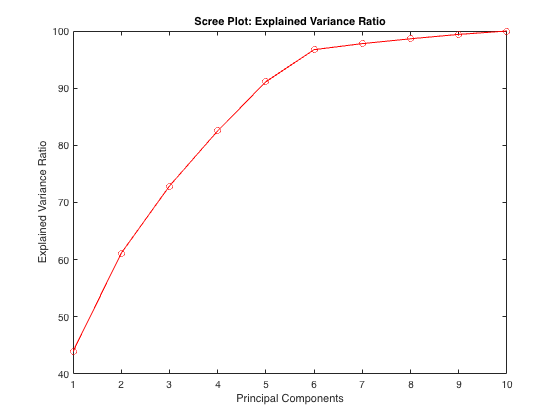

figure;
plot(cumsum(explained), 'ro-');
xlabel('Principal Components');
ylabel('Explained Variance Ratio');
title('Scree Plot: Explained Variance Ratio');

**Variable contributions in each plot**

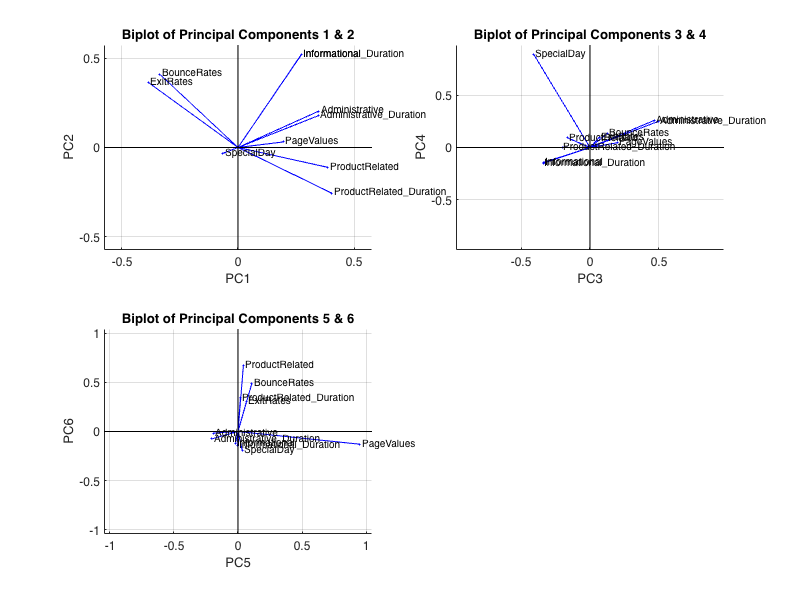

% Biplot of principal components 1 and 2
figure('Position', [100, 100, 800, 600]);
subplot(2,2,1);
biplot(coefficients(:,1:2), 'Scores', [], 'VarLabels', tdata.Properties.VariableNames(1:10));
xlabel('PC1');
ylabel('PC2');
title('Biplot of Principal Components 1 & 2');
set(gca, 'FontSize', 12);

% Biplot of principal components 3 and 4
subplot(2,2,2);
biplot(coefficients(:,3:4), 'Scores', [], 'VarLabels', tdata.Properties.VariableNames(1:10));
xlabel('PC3');
ylabel('PC4');
title('Biplot of Principal Components 3 & 4');
set(gca, 'FontSize', 12);

% Biplot of principal components 5 and 6
subplot(2,2,3);
biplot(coefficients(:,5:6), 'Scores', [], 'VarLabels', tdata.Properties.VariableNames(1:10));
xlabel('PC5');
ylabel('PC6');
title('Biplot of Principal Components 5 & 6');
set(gca, 'FontSize', 12);

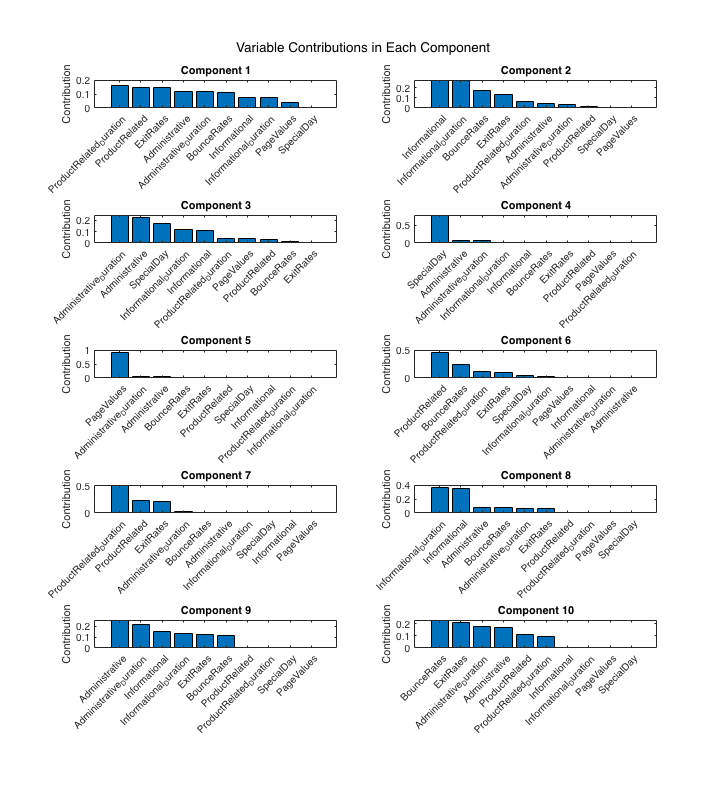

% Perform PCA on the data
[coefficients, ~, ~, ~, explained] = pca(Xnorm);

% Calculate the squared loadings for each variable in each component
squaredLoadings = coefficients.^2;

% Sort the squared loadings in each component in descending order
[sortedLoadings, sortedIndices] = sort(squaredLoadings, 'descend');

% Variable names
variableNames = tdata.Properties.VariableNames(1:10);

% Plot the variable contributions for each component
figure('Position', [100, 100, 800, 1000]);
numComponents = size(sortedLoadings, 2);
for i = 1:numComponents
    subplot(5, 2, i);
    bar(sortedLoadings(:, i));
    ylabel('Contribution');
    title(sprintf('Component %d', i));
    xticklabels(variableNames(sortedIndices(:, i)));
    xtickangle(45);
end
sgtitle('Variable Contributions in Each Component');

**Scatter plot of first six principal components**

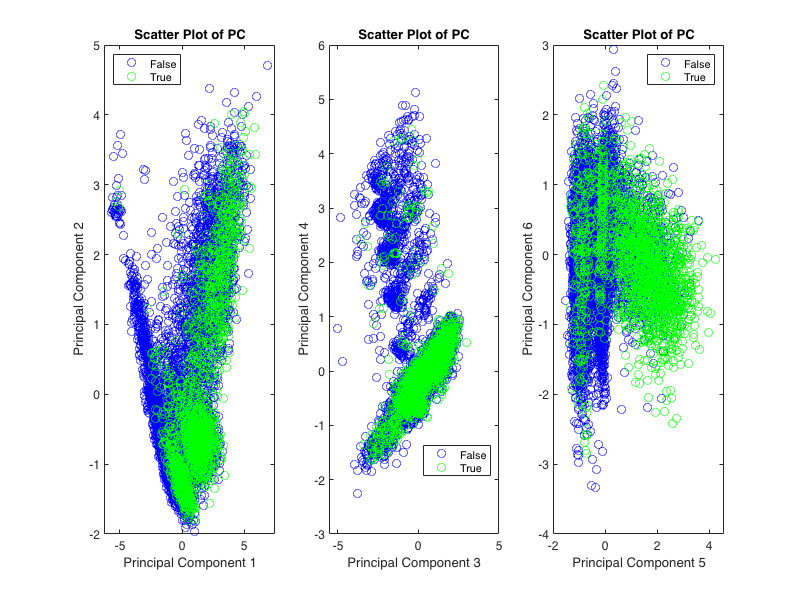

% Scatter plot of the first two principal components
figure('Position', [100, 100, 800, 600]);
subplot(1, 3, 1);
gscatter(scores(:, 1), scores(:, 2), Y, 'bgr', 'o', 8);
xlabel('Principal Component 1');
ylabel('Principal Component 2');
title('Scatter Plot of PC');
legend('False', 'True', 'Location', 'best');
set(gca, 'FontSize', 12);

% Scatter plot of the third and fourth principal components
subplot(1, 3, 2);
gscatter(scores(:, 3), scores(:, 4), Y, 'bgr', 'o', 8);
xlabel('Principal Component 3');
ylabel('Principal Component 4');
title('Scatter Plot of PC');
legend('False', 'True', 'Location', 'best');
set(gca, 'FontSize', 12);

% Scatter plot of the fifth and sixth principal components
subplot(1, 3, 3);
gscatter(scores(:, 5), scores(:, 6), Y, 'bgr', 'o', 8);
xlabel('Principal Component 5');
ylabel('Principal Component 6');
title('Scatter Plot of PC');
legend('False', 'True', 'Location', 'best');
set(gca, 'FontSize', 12);

**Scatter plot of first three principal components**

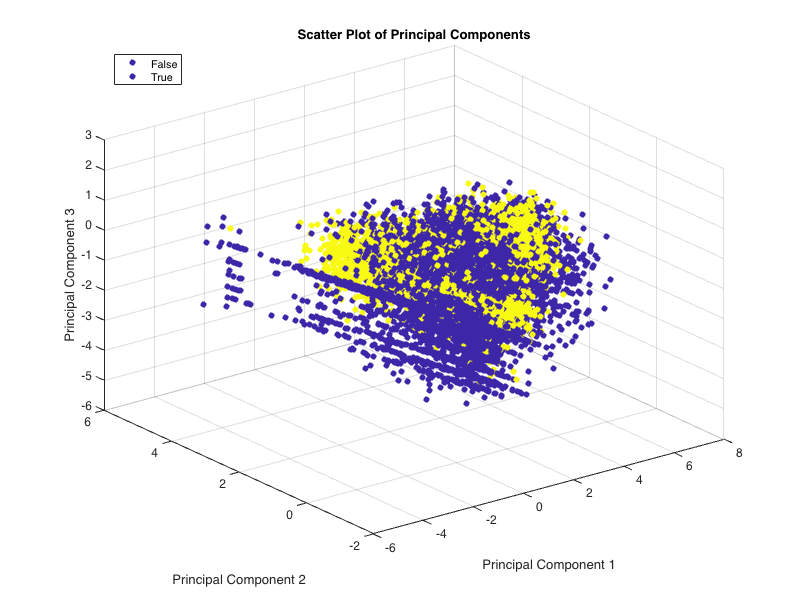

figure('Position', [100, 100, 800, 600]);
scatter3(scores(:, 1), scores(:, 2), scores(:, 3), [], Y, 'filled');
hold on;
scatter3(scores(:, 4), scores(:, 5), scores(:, 6), [], Y, 'filled');
xlabel('Principal Component 1');
ylabel('Principal Component 2');
zlabel('Principal Component 3');
title('Scatter Plot of Principal Components');
legend('False', 'True', 'Location', 'best');
set(gca, 'FontSize', 12);

## (2) LDA: Linear Unsupervised

% Use Revenue as label to do PCA
Xnorm=normalize(table2array(tdata(:,1:10)));
labels=tdata.Revenue;
[Y, V, lambda] = LDA(Xnorm, labels);

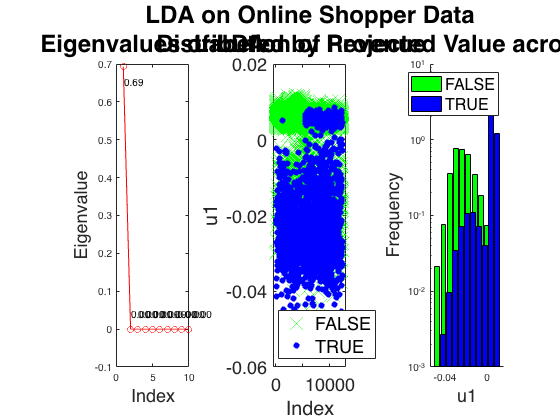

figure; 

% plot 1: eigenvalues
subplot(1,3,1)
plot(1:size(lambda, 1), lambda, 'ro-');
text(1.04, lambda(1)-0.04, {sprintf('%.2f',lambda(1))});
text(2.04, lambda(2)+0.04, {sprintf('%.2f',lambda(2))});
for i=3:size(lambda, 1)
    text(i, lambda(i)+0.04, {sprintf('%.2f',lambda(i))});
end
xlabel('Index', 'fontsize',18)
ylabel('Eigenvalue', 'fontsize', 18)
title('Eigenvalues of LDA','fontsize',24);

% Plot 2
subplot(1,3,2)
gscatter(1:size(Y,1),Y(:,1), data.Revenue, 'gb', 'x.', 18)
set(gca, 'fontsize', 18)
xlabel('Index')
ylabel('u1')
xlim([-500, 13000])
title({'LDA on Online Shopper Data', 'Labeled by Revenue'} , 'fontsize', 24)
legend(levels, 'Location', 'Southwest','fontsize', 18)

% plot 3: u1 distribution by labels
subplot(1,3,3)
hold on
X1_projected = Y(data.Revenue=='TRUE', 1);
X2_projected = Y(data.Revenue=='FALSE', 1);
% plot histogram and rotate it
angle = 180/pi * atan(V(2,1)/V(1,1));
[hy1, hx1] = hist(X1_projected);
[hy2, hx2] = hist(X2_projected);
hy1 = hy1 / sum(hy1); % normalize
hy2 = hy2 / sum(hy2); % normalize
scale = 4; % set manually
h1 = bar(hx1, scale*hy1,'g');
h2 = bar(hx2, scale*hy2,'b');
set([h1, h2],'ShowBaseLine','off')
set(gca,'YScale','log')
hold off 
xlabel('u1', 'fontsize',18)
ylabel('Frequency', 'fontsize', 18)
title('Distribution of Projected Value across Revenue Levels','fontsize',24)
legend(levels, 'Location', 'Northeast','fontsize', 16)

## (3) MDS: Classical Multidimensional Scaling

% Calculate dist matrix
numerical_euclidean_Dist = squareform(pdist(table2array(tdata(:,1:10)), "euclidean"));
numerical_cityblock_Dist = squareform(pdist(table2array(tdata(:,1:10)), "cityblock"));
numerical_cosine_Dist = squareform(pdist(table2array(tdata(:,1:10)), "cosine"));
numerical_correlation_Dist = squareform(pdist(table2array(tdata(:,1:10)), "correlation"));

% Euclidean distance
[Ymds_euclidean, e_euc] = cmdscale(numerical_euclidean_Dist, 10);
% City block distance
[Ymds_cityblock, e_city] = cmdscale(numerical_cityblock_Dist, 10);
% City block distance
[Ymds_cosine, e_cos] = cmdscale(numerical_cosine_Dist, 10);
% Correlation distance
[Ymds_correlation, e_corr] = cmdscale(numerical_correlation_Dist, 9);

embeded_euclidean_Dist = squareform(pdist(Ymds_euclidean(:,1:3), "euclidean"));
embeded_cityblock_Dist = squareform(pdist(Ymds_cityblock(:,1:3), "cityblock"));
embeded_cosine_Dist = squareform(pdist(Ymds_cosine(:,1:3), "cosine"));
embeded_correlation_Dist = squareform(pdist(Ymds_correlation(:,1:3), "correlation"));

% Stress values
stress_euclidean = norm(numerical_euclidean_Dist-embeded_euclidean_Dist, "fro")/norm(numerical_euclidean_Dist,"fro");
stress_cityblock = norm(numerical_cityblock_Dist-embeded_cityblock_Dist, "fro")/norm(numerical_cityblock_Dist,"fro");
stress_cosine = norm(numerical_cosine_Dist-embeded_cosine_Dist, "fro")/norm(numerical_cosine_Dist,"fro");
stress_correlation = norm(numerical_correlation_Dist-embeded_correlation_Dist, "fro")/norm(numerical_correlation_Dist,"fro");

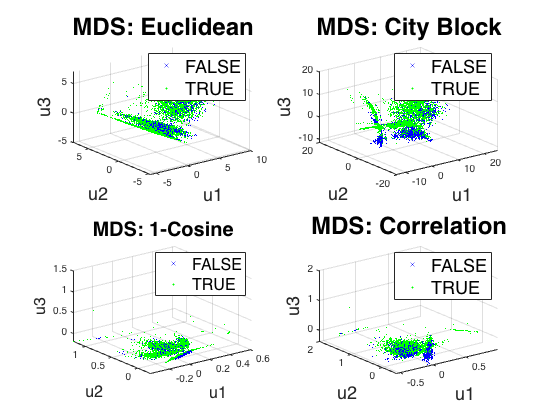

figure;
subplot(2,2,1)
% Euclidean distance
scatter3(Ymds_euclidean(data.Revenue=='TRUE',1), Ymds_euclidean(data.Revenue=='TRUE',2), Ymds_euclidean(data.Revenue=='TRUE',3), 4, 'b', 'x');
hold on;
scatter3(Ymds_euclidean(data.Revenue=='FALSE',1), Ymds_euclidean(data.Revenue=='FALSE',2), Ymds_euclidean(data.Revenue=='FALSE',3), 6, 'g', '.');
hold off;
xlabel('u1', 'fontsize',18)
ylabel('u2', 'fontsize',18)
zlabel('u3', 'fontsize',18)
title({'MDS: Euclidean'} , 'fontsize', 24)
legend(levels, 'Location', 'Northeast','fontsize', 18)

subplot(2,2,2)

scatter3(Ymds_cityblock(data.Revenue=='TRUE',1), Ymds_cityblock(data.Revenue=='TRUE',2), Ymds_cityblock(data.Revenue=='TRUE',3), 4, 'b', 'x');
hold on;
scatter3(Ymds_cityblock(data.Revenue=='FALSE',1), Ymds_cityblock(data.Revenue=='FALSE',2), Ymds_cityblock(data.Revenue=='FALSE',3), 6, 'g', '.');
%zlim([-0.5, 0.5])
hold off;
xlabel('u1', 'fontsize',18)
ylabel('u2', 'fontsize',18)
zlabel('u3', 'fontsize',18)
title({'MDS: City Block'} , 'fontsize', 24)
legend(levels, 'Location', 'Northeast','fontsize', 18)

subplot(2,2,3)
% Cosine distance
scatter3(Ymds_cosine(data.Revenue=='TRUE',1), Ymds_cosine(data.Revenue=='TRUE',2), Ymds_cosine(data.Revenue=='TRUE',3), 4, 'b', 'x');
hold on;
scatter3(Ymds_cosine(data.Revenue=='FALSE',1), Ymds_cosine(data.Revenue=='FALSE',2), Ymds_cosine(data.Revenue=='FALSE',3), 6, 'g', '.');
%zlim([-0.5, 0.5])
hold off;
xlabel('u1', 'fontsize',16)
ylabel('u2', 'fontsize',16)
zlabel('u3', 'fontsize',16)
title({'MDS: 1-Cosine'} , 'fontsize', 20)
legend(levels, 'Location', 'Northeast','fontsize', 16)

subplot(2,2,4)
% Correlation distance
scatter3(Ymds_correlation(data.Revenue=='TRUE',1), Ymds_correlation(data.Revenue=='TRUE',2), Ymds_correlation(data.Revenue=='TRUE',3), 4, 'b', 'x');
hold on;
scatter3(Ymds_correlation(data.Revenue=='FALSE',1), Ymds_correlation(data.Revenue=='FALSE',2), Ymds_correlation(data.Revenue=='FALSE',3), 6, 'g', '.');
%zlim([-0.5, 0.5])
hold off;
xlabel('u1', 'fontsize',18)
ylabel('u2', 'fontsize',18)
zlabel('u3', 'fontsize',18)
title({'MDS: Correlation'} , 'fontsize', 24)
legend(levels, 'Location', 'Northeast','fontsize', 18)

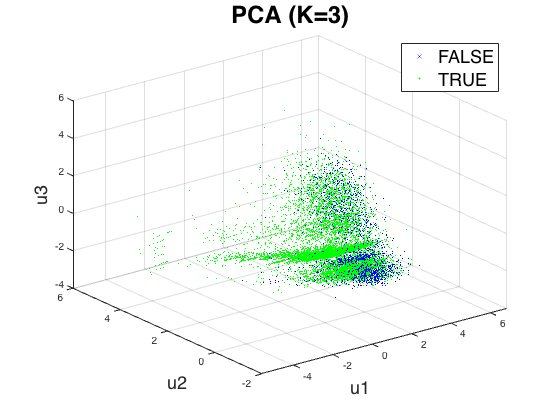

% plot 5: PCA
[U,S] = svds(Xnorm - mean(Xnorm,1), 3);
Ypca = U .* diag(S)';

figure;
scatter3(Ypca(data.Revenue=='TRUE',1), Ypca(data.Revenue=='TRUE',2), Ypca(data.Revenue=='TRUE',3), 4, 'b', 'x');
hold on;
scatter3(Ypca(data.Revenue=='FALSE',1), Ypca(data.Revenue=='FALSE',2), Ypca(data.Revenue=='FALSE',3), 6, 'g', '.');
hold off;
xlabel('u1', 'fontsize',18)
ylabel('u2', 'fontsize',18)
zlabel('u3', 'fontsize',18)
title({'PCA (K=3)'} , 'fontsize', 24)
legend(levels, 'Location', 'Northeast','fontsize', 18)

function [Y, V, lambda] = LDA(X, labels)
    classes = unique(labels);
    c = size(classes, 1);
    [n, d] = size(X);
    Ng = zeros(c, 1);
    Mg = zeros(c, d);
    M = mean(X);
    for j = 1:c
        Xj = X(labels==classes(j),:);
        Ng(j) = size(Xj, 1);
        Mg(j,:) = mean(Xj);
    end
    Mtilde = zeros(c, d);
    for j = 1:c
        Mtilde(j,:) = sqrt(Ng(j))*(Mg(j,:) - M);
    end
    Xtilde = zeros(size(X));
    for i = 1:n
        idx = find(classes==labels(i));
        Xtilde(i,:) = X(i,:) - Mg(idx,:);
    end
    Sb = transpose(Mtilde)*Mtilde;
    Sw = transpose(Xtilde)*Xtilde;
    [V, lambda] = eig(Sb, Sw);
    lambda = diag(lambda);
    [lambda, sortOrder] = sort(lambda, 'descend');
    V = V(:,sortOrder);
    Y = X*V;
end